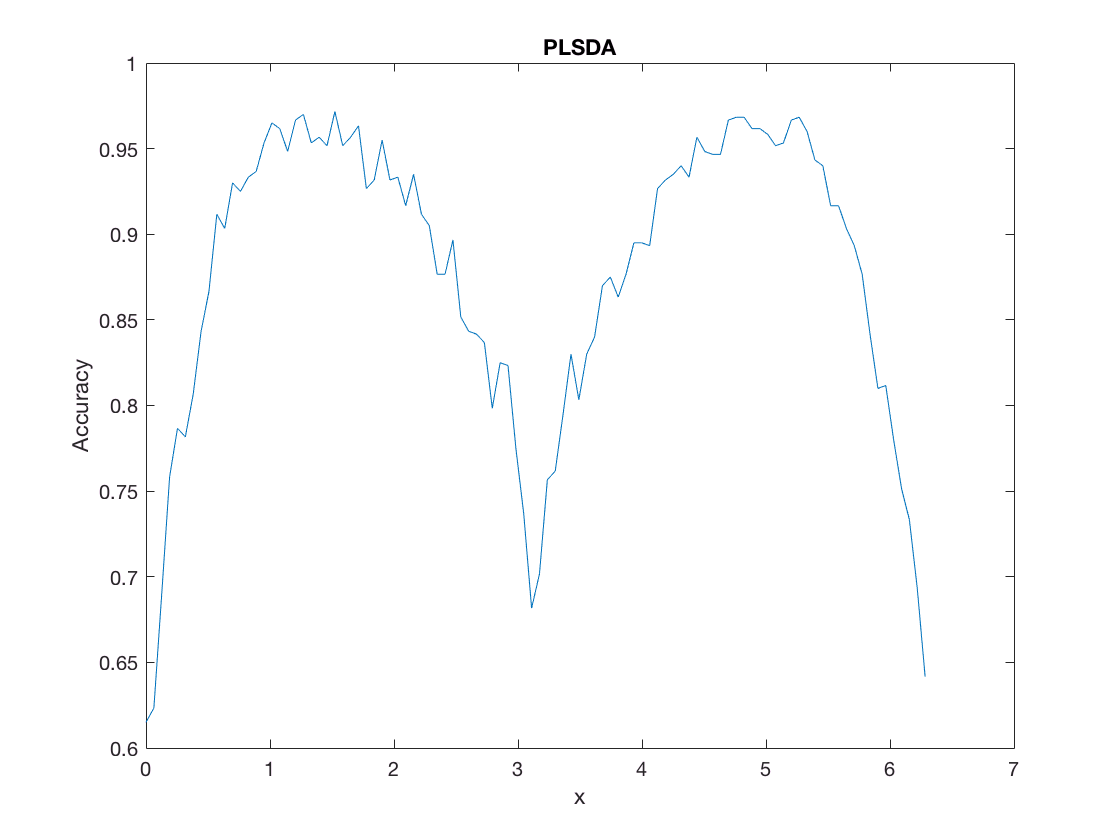

% Question 1 
mu0 = [0,0];
mu1 = [4,0];
Sigma = eye(2);
N = 200;
rng(2018)
numX = 100;
percentCorr = zeros(1,numX);
count =1;
for x = linspace(0,2*pi,numX)
    mu2 = 4*[cos(x),sin(x)] + mu0;
    ds1 = prtDataGenUnimodal(N,mu0,mu1,Sigma,Sigma);
    ds2 = prtDataGenUnimodal(N,mu0,mu2,Sigma,Sigma);
    ds2.Y(ds2.Y==1) = 2;        
    ds = catObservations(ds1,ds2.retainObservations(ds2.Y==2));
    cls = prtClassPlsda + prtDecisionMap;
    results = cls.kfolds(ds,2);
    percentCorr(count) = prtScorePercentCorrect(results);
    count = count +1;
end

figure;
plot(linspace(0,2*pi,numX),percentCorr)
title('PLSDA');
xlabel('x');
ylabel('Accuracy');

% Question 2
mu0 = [0,0];
mu1 = [4,0];
Sigma = eye(2);
N = 200;
rng(2018)
numX = 100;
percentCorr = zeros(1,numX);
count =1;

for x = linspace(0,2*pi,numX)
    mu2 = 4*[cos(x),sin(x)] + mu0;
    ds1 = prtDataGenUnimodal(N,mu0,mu1,Sigma,Sigma);
    ds2 = prtDataGenUnimodal(N,mu0,mu2,Sigma,Sigma);
    ds2.Y(ds2.Y==1) = 2;        
    ds = catObservations(ds1,ds2.retainObservations(ds2.Y==2));
    cls = prtPreProcZmuv + prtClassBinaryToMaryOneVsAll('baseClassifier',prtClassFld) +  ...
          prtDecisionMap;
    results = cls.kfolds(ds,2);
    percentCorr(count) = prtScorePercentCorrect(results);
    count = count +1;
end

figure;
plot(linspace(0,2*pi,numX),percentCorr)
title('ZMUV+FLD');
xlabel('x');
ylabel('Accuracy');


% Extra Credit: 
mu0 = [0,0];
mu1 = [4,0];
Sigma = eye(2);
N = 200;
rng(2018)
numX = 100;
percentCorr = zeros(1,numX);
count =1;

for x = linspace(0,2*pi,numX)
    mu2 = 4*[cos(x),sin(x)] + mu0;
    ds1 = prtDataGenUnimodal(N,mu0,mu1,Sigma,Sigma);
    ds2 = prtDataGenUnimodal(N,mu0,mu2,Sigma,Sigma);
    ds2.Y(ds2.Y==1) = 2;
    ds = catObservations(ds1,ds2.retainObservations(ds2.Y==2));
    cls = prtClassBinaryToMaryOneVsAll('baseClassifier',prtClassFld) +  ...
          prtDecisionMap;
    results = cls.kfolds(ds,2);
    percentCorr(count) = prtScorePercentCorrect(results);
    count = count +1;
end 
figure;
plot(linspace(0,2*pi,numX),percentCorr)
title('FLD');
xlabel('x');
ylabel('Accuracy');